# Tutorial for classifying objects in ultrasound data 

This tutorial is designed to be used as a guide of how to use the Matlab Statistics and Machine Learning toolbox in combination with the Verasonics Vantage system for live classification of targets in ultrasound image data. It contains four easy steps that help  the user to understand the overall classification workflow. The parameters in this tutorial work are best for classifying the large hyperechoic circles in images taken from a CIRS Multi-Purpose Multi-Tissue Ultrasound Phantom Model 040GSE.

This tutorial requires the use of an L11-5v transducer, MATLAB's Statistics and Machine Learning Toolbox, and MATLAB's Image Processing Toolbox.

*Please note that this is only an example that is intended to show the possibilities of incorporating machine learning methods into Vantage scripts for live classifications. The methods described here should NOT be understood as ready-made tools for classifying any arbitrary objects (e.g., biological tissues) and should not be used as such. Verasonics does not guarantee that similar results are achieved as described in this example if these methods are applied to other objects than the hyperechoic inclusions of the CIRS Multi-Purpose Multi-Tissue Ultrasound Phantom (Model 040GSE). Each segmentation and detection problem requires specific considerations and careful statistical evaluation to evaluate the validity of the models, which is out of the scope of Verasonics this Machine-Learning example.*   

The overall steps described in this tutorial are:

- Step1: Acquire Data: Save image data.

- Step 2: Training Preparation: Create training data from the acquired data and set training parameters.

- Step 3: Train Classifier: Train the classifier with training data and parameters.

- Step 4: Classify Image: Classify images with trained classifier.

*Version 1.0 | 2019-10-25*

*Author: Ellyn Cashdollar & Dr. Daniel Rohrbach *

*Copyright 2001-2019 Verasonics, Inc.  Verasonics Registered U.S. Patent and Trademark Office.*

## Step 1: Acquire data

Acquire data from a phantom. This data will be used to create a training data set for the classifier to be trained with. To save image data, use the SetUpL11_5vFlashAngles_SaveImages.m script. This script uses the Process-Storage-Class feature introduced in the 4.0.1 release. The storage class allows the user to export, receive and image data directly to disk.

The image data will be saved under vantage/UserData/AI. 

The settings used for imaging should be saved and re-used for classification.

cd(vsv.file.getVSXDir);
% Set up for saving images
SetUpL11_5vFlashAngles_SaveImages

% Start Vantage software
VSX

## Step 2: Training Preparation

This section creates training data and sets parameters for training the classifier. 

### Create Training Data

This step creates training data by allowing the user to manually select the objects  they want to classify in the acquired data.

The image data is then saved in a .mat file with the correct classifications (map) and the corresponding image. Inputs to this step are the file path for the acquired data, the name of the file to save the training data under, and the number of training images to be in the training data set. 

To create the training image files a figure will pop up showing one of the images in the data set. Select the object to be classified by placing several connected points around the object. Once finished selecting the object, double click on any point . This will prompt a display that will ask if there are any more objects to be trained for in the current image. If there are, select 'yes', if not select 'no'. Selecting 'no' will cause the next image for user classification in the training data set to appear. Continue this process until all images in the training data set have been completed. The training data will be saved in the inputted folder name on the path specified in trainingDataPath. The figure below is an example of how to create a training image.

**Training is added to all folder names.

% Define training data folder
trainingDataPath = fullfile( vsv.file.getVSXDir, ['UserData' filesep 'AI'] );

% Contruct training data object with the training data file path
trainingData = vsv.ai.VSVAICreateTrainingData( trainingDataPath );

% Set number of images to be in training data set
% change this to a larger number to train more images
numberOfTrainingImages = 2;

% Save training data in the folder 'AITraining' ** with a specified number of images
% for training. 

trainingData.createTrainingData( 'AI', numberOfTrainingImages );


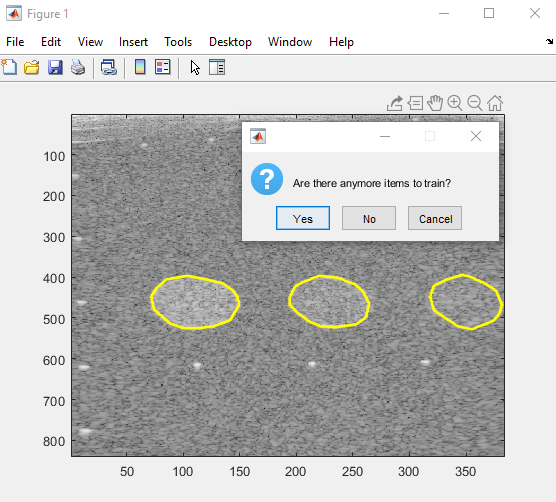

* This figure displays manual selection process of the large hyperechoic circles in the image. All of the hyperechoic circles have been selected. The user is presented with the opportunity to select another object in the image or move on to the next image. In this case, the user would select 'no' as all of the large hyperechoic circles in the image have been selected.*

### Training Methodology

The classifier is trained by extracting features out of each ultrasound image. These features are extracted by cropping out a small portion of the image (imagePatch) and extracting the features from this smaller part of the image. Size of the imagePatch is defined by the user using the **kernel **field. The location of the imagePatch in the image moves by a user specified amount called the **stepSize.** The stepSize should always be smaller than either dimension of the imagePatch. This allows for the imagePatches to overlap resulting in better classifications. 

To extract the features from an imagePatch, it is linearized into a row vector. Each column of this vector is a feature. To extract the features from the entire image, all of the imagePatches from the image are combined row-wise into a single feature data matrix. To reduce the number of features, this matrix is filtered using a sparse filter. The number of features that the sparse filter finds can be specified with the input parameter **sparseFilteringFeatures**. Sparse filtering was chosen because it finds characteristic features of nearly equal weight.

An image filter is applied to the original ultrasound image to make the features of the target object more pronounced and distinct. Applying different filters can highlight different objects in the image. The filter applied to the image can be controlled by the input parameter **imageFilter**.

Training the classifier requires the input of feature data as well as a logical column vector (group data) describing whether or not the respective row in the feature data matrix has the training object in it or not. This information is gathered from the maps in the training data. To make sure that each row in the feature data and group data correspond to the same image patch, an identical approach for extracting features from an image is used on the map data to create the group data. However, the group data needs to be  simplified from a matrix to a vector  as the group data cannot be a matrix unlike the feature data. To accomplish this, the average of each row of the group data in matrix form is compared to a threshold value. This row average is a measure of how much of the target object  is in the corresponding imagePatch. If the row average is larger than the threshold value, the corresponding imagePatch is considered to have the object in it. This threshold value is controlled by the input parameter **thresholdSimplifyGroupData**.

The group data vector relays what rows of the feature data contain features of the object.

This information is used to train the classifier to identify the features of the target object in an image. To improve classification and decrease misclassifications another threshold, **thresholdPartialClassification**, is added to allow for the user to exclude image patches that contain more than the threshold for simplifying the group data but not enough features of the object to be used for training the classifier. 

The type of classification model to train is set by the user through the input parameter **modelType**. The different classification models avaliable for training are provided in the MATLAB Statistics and Machine Learning Toolbox.

Two main methods are used to improve the speed of training and classification; resizing the image and specifying a smaller area within the image to classify and train on. Resizing an ultrasound image speeds up training and classification by reducing the amount of data that needs to be processed. It also helps to better identify important features in the image as resizing will reduce the noise in the image. The amount the image is resized is controlled by the input parameter **imageResizeFactor**. The other method is mainly used when the location of the object to be identified in the image is known and relatively stationary. The input parameters **rowsForClassification** and **columnsForClassification** control the rows and columns respectively of where in the image to search for and identify the desired object. The area specified by rowsForClassification and columnsForClassification must be larger than the kernelSize so that features can be extracted from the specificed search area. This method is best for very large images where resizing the image would decrease the ability to identify the desired object in the image.

### Training Parameters

Listed below is a summary of all of the parameters used in training and classification.

- kernelSize: Defines how much of the image is cropped out and used to determine the features for classification and training. (@type numeric)

- stepSize: Defines how much to incrementally move the cropped area through the image. (@type numeric)        

- thresholdSimplifyGroupData: Determines what value should be considered as a correct classification when simplifying the map data in training. (@type numeric)

- thresholdPartialClassification: Percentage of the object you trained to classify that will be used as true when training the classifier. (@type numeric)

- rowsForClassification: Rows in the full scale image that will be classified.** (@type numeric)

- columnsForClassification: Columns in the full scale image that will be classified.** (@type numeric)

- sparseFilteringFeatures: Number of features the sparse filter will find in the input data. (@type numeric)

- imageResizeFactor: The percent, in decimal form, that the full scale image is to be reduced to. (@type numeric)

- imageFilter: Image filter to be used to filter data. (@type vsv.ai.imgfilter)

- modelType: Type of the classifier model to be trained. (@type Matlab classification model)

**To select the entire image set both rowsForClassification and columnsForClassification to [ ].

% Define a training parmaeters
parameters = vsv.ai.VSVAIParameters('kernel', ones( 180, 80 ),...
                                    'stepSize', 1, ...
                                    'thresholdSimplifyGroupData', 0.25, ...
                                    'thresholdPartialClassification', 0.50, ...
                                    'rowsForClassification', [], ...
                                    'columnsForClassification', [], ...
                                    'sparseFilteringFeatures', 150, ...
                                    'imageResizeFactor', 0.125, ...
                                    'imageFilter', vsv.ai.imgfilter.BtwImageFilter, ...
                                    'modelType', 'ClassificationDiscriminant');

## Step 3: Train classifier

This step implements the training procedure discussed above.

### Train Classification Model

% Construct the classifier training object
training = vsv.ai.VSVAITraining( parameters );

% Train a classification model and a sparse filtering model to be used in
% the classification process. The first input is the folder where the
% trainingData is located (trainingData). The second input controls whether
% the progress of training is displayed in the command window.
model = training.trainClassifier( [trainingDataPath filesep 'AITraining'], 'on' );

% you have access to the the model components
classificationModel  = model.classificationModel;
sparseFilteringModel = model.sparseFilteringModel;

### Save Classification Model

Save the trained classifier in the same folder as the acquired data. This is necessary for live classification, as the classifier needs to be loaded into the live classification script. It also allows for the classifier to be used and referenced again in the future.

% Save trained classifier model
save( [trainingDataPath filesep 'ClassificationModel.mat'], 'model' );

## Step 4: Classify Images

This section goes through how to use the classifier.

### Classification Process

To classify an image, the classifier needs the input data to be in the same form as the data used in training it. This means that to classify an image the image first needs to be filtered with any image filter used on the  training images. Then the features need to be extracted from the image using image patches and then the number of features from image patches needs to be reduced with the sparse filter used in the training. These steps will covert the image to the correct format to be used with the classifier. The classifier then returns a score indicating whether each image patch in the image contains the target object. These scores are then summed together for overlapping image patches creating a map of specifying where the classifier found the target object. A threshold is required to make the map binary. This threshold is called the **mapThreshold**. If the value of the summed score is greater than or equal to the mapThreshold the value is replaced with a one. All other values in the map are replaced with zeros. 

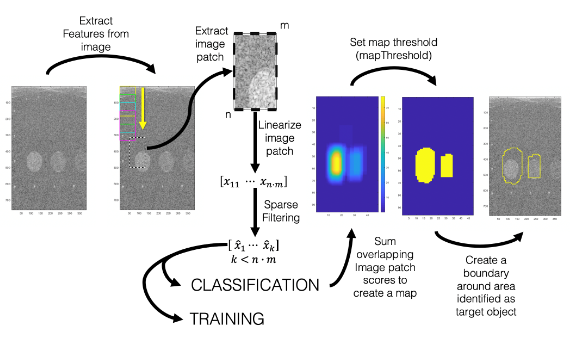

*Graphical summary of the process used for training and classification.*

### Classify Single Image

The figure below shows the classification of the hyperechoic circle in the image.

% Pick image to classify
fileNames = vsv.file.FileTools.listFilesRegexp( trainingDataPath, '\.vrs' );

image = vsv.file.readVRSFile([trainingDataPath filesep fileNames{1}]);

% If you want to try out a pretrained classifier you can load the following
% to obtain a classifier that is pretrained to detect the bright inclusions
% of a CRIS phantom
%
% % model
% modelPath = fullfile( vsv.file.getVSXDir, ['UserData' filesep 'AI' filesep 'brightCircleModel.mat'] );
% % load the classifier from file
% classifier = vsv.ai.VSVClassifier.loadClassifier(modelPath);

% Construct classifier object
classifier = vsv.ai.VSVClassifier( model );

% Set map threshold
mapThreshold = 20;

% create classification results
clResults = classifier.classifyImage(image, mapThreshold);

% Display classification of a single image
classifier.displayImageClassification( clResults, image );

subplot(1,2,1, gca); 
subplot(1,2,2); 
imagesc( clResults.scoreMapFull );


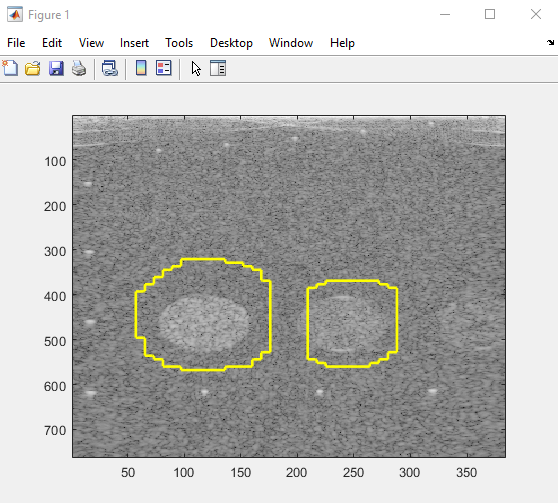

*This figure shows the correct classification of the hyperechoic circles in the ultrasound image. The classifier was trained with the training parameters specified in the code above. *

**Classify Live Ultrasound Data**

To classify live data use SetUpL11_5vFlashAngles_Classify.m script with the saved  classification model in vantage/UserData/AI. The same settings that were  used to take the image data in step 1 should be used in the live classification for accurate results.

Running the live script is not Possible from within the live turorial. Please use the vsvAIDemo.m file

Use the Start button to start live classification once the Vantage GUI has been started.